# Plot step response data recorded with the arduino

## Read and plot the recorded data

The filename below belongs to the file with the step response experiment data. The step response data was recorded for input steps of +5 and -5 degrees. This value is fixed in the microcontroller code for the step response experiment, and it needs to be set here by hand. We also need to copy the time step (5ms= 0.005s) used in the arduino sketch. 

clear all;
close all; 
filename= "../arduino/record_open_loop_step_response_data_for_matlab/data_for_matlab.txt"; 
uStep= 5; % deg, degrees
delta_t= 0.005; % seconds

We are now ready to read the data and to extract the time points and output values from it.

data = readtable(filename); 
tData = data{:, 1}'; % note transpose operator
yData = data{:, 2}';
t0= tData(1);
numpoints= length(yData);

We need to divide all time data by 1e6 to to convert microseconds to seconds. 

tData= tData* 1e-6; 

We first plot the entire set of recorded data, which contains more than one step response. 

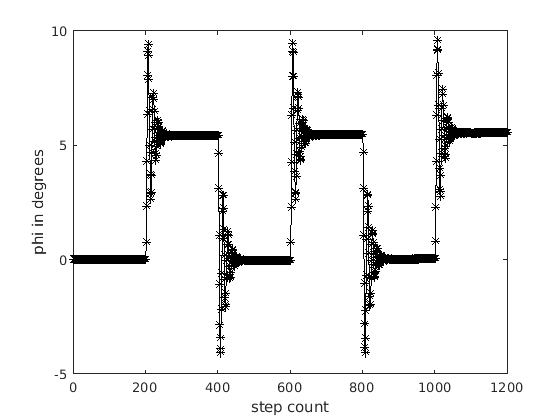

figure(); 
plot(yData, '-*', 'Color', 'black'); 
xlabel("step count");
ylabel("phi in degrees"); 

Now let's select a single step response to work with. Since the arduino generates a step input every 200 timesteps (which corresponds to a second for the sample time of 5ms), we can select steps 200 to 400. Actually, 200 to 300 suffice, since a new steady state has been reached after 100 steps already. Play with these numbers to check if we picked a good interval. (Try 195 to 250, for example. Also try 199 to 250 and 201 to 250.)

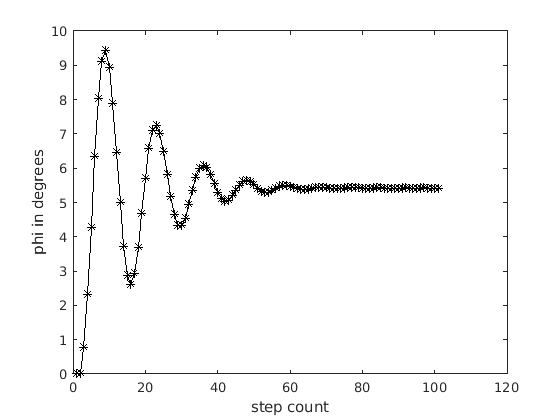

kstart= 200;
kstop= 300; 
figure();
plot(yData(kstart:kstop), '-*', 'Color', 'black'); 
xlabel("step count"); 
ylabel("phi in degrees"); 

Having selected an appropriate interval of steps, we can discard all other data. We can also reset the time of the first data point to be t=0s.

Let's also include the input signal for comparison.

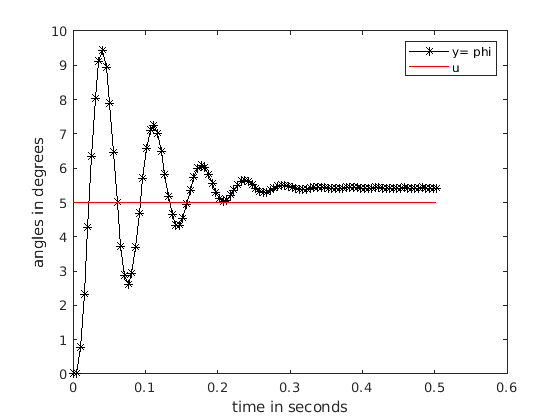

figure(); 
tData= tData(kstart:kstop)- tData(kstart); 
yData= yData(kstart:kstop); 
plot(tData, yData, '-*', 'Color', 'black');
hold on;
uData= uStep* ones(1, length(tData)); 
plot(tData, uData, '-', 'Color', 'red'); 
legend("y= phi", "u"); 
xlabel("time in seconds"); 
ylabel("angles in degrees"); 

Note that the $y$ may reach a new steady state value that is not equal to the input step. This must be accounted for with a static gain $K \ne 1$ in the transfer function. The output $y$ and input step may even have opposite signs, which can be accounted for by $K< 0$.